# Nedkøling af brine

clc; clear all;

brine = importdata("NiceBrineData.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");


ind = 10;

brine_Tefordamp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper")

brine_Tefordamp =      6


brine_Tffordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

brine_Tffordamp =      9


brine_Tbrine = find(brine.textdata(1,2:end) == "Brinetemperatur")

brine_Tbrine =      4



brine_Tffordamp = brine.data(ind:end-ind, brine_Tffordamp);
brine_Tefordamp = brine.data(ind:end-ind, brine_Tefordamp);
brine_Tbrine = brine.data(ind:end-ind, brine_Tbrine);


ind_plot = find(max(brine_Tbrine) == brine_Tbrine)

ind_plot =    110



xs = length(brine_Tffordamp(ind:end))*2*0.142/60

xs =           33.6634666666667



xlin = linspace(1,xs,length(brine_Tffordamp(ind_plot:end)));


lps = length(xlin);

errlin = zeros(1,lps);

fejl = 2*0.9798;

for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

gg = find(errlin == 1);
xlin(gg)

ans =           3.32478531830932          5.65422952503209          7.98367373175486          10.3131179384776          12.6425621452004          14.9720063519232          17.3014505586459          19.6308947653687          21.9603389720915          24.2897831788142           26.619227385537          28.9486715922598          31.2781157989825          33.6075600057053


brine_Tffordamp(gg)

ans =                 -14.950308
                -15.642376
                -15.725944
                -15.945905
                -15.966844
                -16.068731
                 -15.88234
                -15.793901
                -15.725322
                -15.498136


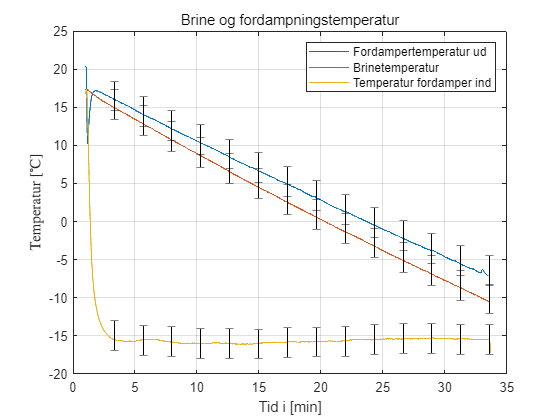



figure

plot(xlin, brine_Tefordamp(ind_plot:end))

hold on
plot(xlin, brine_Tbrine(ind_plot:end))
plot(xlin, brine_Tffordamp(ind_plot:end))


errorbar(xlin(gg), brine_Tffordamp(gg),fejl,"k")
errorbar(xlin(gg), brine_Tefordamp(gg),fejl,"k")
errorbar(xlin(gg), brine_Tbrine(gg),fejl,"k")

hold off


title("Brine og fordampningstemperatur","FontWeight","normal")
grid("on")
legend("Fordampertemperatur ud","Brinetemperatur","Temperatur fordamper ind","location","northeast")

xlabel("Tid i [min]")
ylabel("Temperatur $[^\circ\mathrm{C}]$","Interpreter","latex")

exportgraphics(gcf,"FordampBrineTempsBrine.png")

T_komp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp =      6



T_fordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp =      9


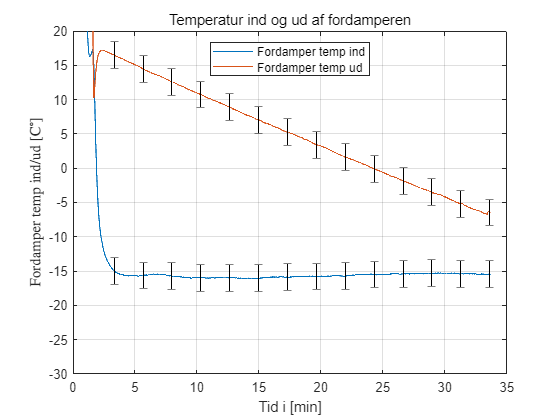


T1 = brine.data(ind:end-ind-9-100, T_komp);
T4 = brine.data(ind:end-ind-9-100, T_fordamp);

errlin = zeros(1,lps);

fejl = fejl;

for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end


figure


plot(xlin, T4)
ylabel("Fordamper temp ind/ud [C$^\circ$]", "Interpreter","latex")

hold on

plot(xlin, T1)

errorbar(xlin(gg), T1(gg),fejl,"k")
errorbar(xlin(gg), T4(gg),fejl,"k")


hold off

ylim([-30,20])

grid("on")
legend("Fordamper temp ind","Fordamper temp ud","Location","north")
title("Temperatur ind og ud af fordamperen","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"FordampTempsBrine.png")

## Phi

R = 0.009299;

phi = -(brine_Tffordamp(ind_plot:end) - brine_Tbrine(ind_plot:end))/R;

errlin = zeros(1,lps);

tpdf = brine_Tffordamp(ind_plot:end) - brine_Tbrine(ind_plot:end);

fejl = -(max(tpdf))/R

fejl =           9.52360468867632



for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

phimin = 1249.36;



max(brine_Tffordamp(ind_plot:end))

ans =                   17.27011


max(brine_Tbrine(ind_plot:end))

ans =                  17.389936


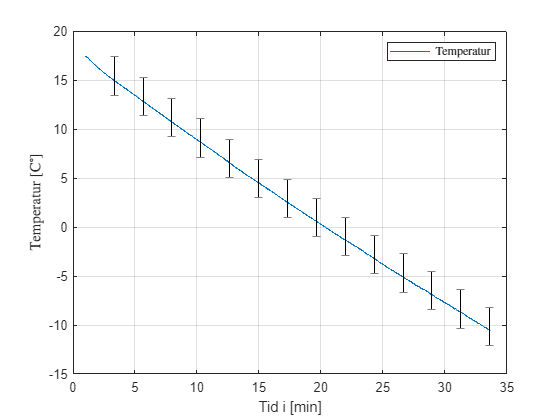


figure

%yyaxis left
%plot(xlin, phi)


%ylabel("Varmestrøm [W]")

%yyaxis right
plot(xlin, brine_Tbrine(ind_plot:end))

hold on
errorbar(xlin(gg),brine_Tbrine(gg),2*0.9798,"k")
hold off

ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

%title("Mulig varmestrøm gennem fordamperen og brinen","FontWeight","normal")
grid("on")
xlabel("Tid i [min]")


legend("Temperatur","Interpreter","latex")

exportgraphics(gcf,"BrineTempBrine.png")

enbr = 18100;


## Tryk

brine_lavtryk = find(brine.textdata(1,2:end) == "Tryk lav")

brine_lavtryk =     13


brine_hojtryk = find(brine.textdata(1,2:end) == "Tryk høj")

brine_hojtryk =     12


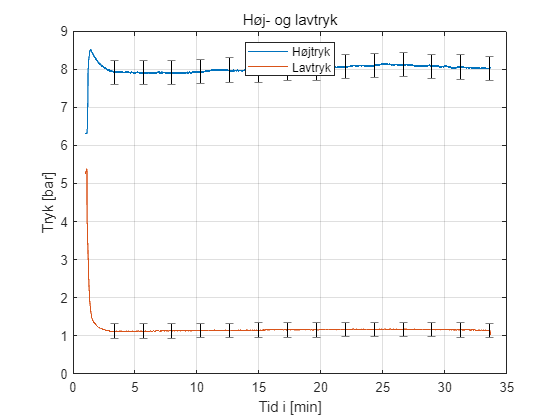


brine_lavtryk = brine.data(ind_plot:end-19, brine_lavtryk) + 1;
brine_hojtryk = brine.data(ind_plot:end-19, brine_hojtryk) + 1;

errlin_hoj = zeros(1,lps);
errlin_lav = zeros(1,lps);

fejlhoj = 2* 0.008*20;
fejllav = 2*0.008*12;

for i = 1:lps
    if mod(i,500) == 0
        errlin_hoj(i) = fejlhoj;
        errlin_lav(i) = fejllav;
    else
        errlin_hoj(i) = 0;
        errlin_lav(i) = 0;
    end
    
end

figure


plot(xlin, brine_hojtryk)


hold on
plot(xlin, brine_lavtryk(1:end))
errorbar(xlin(gg),brine_hojtryk(gg),fejlhoj,"Color","k","LineStyle","none")
errorbar(xlin(gg),brine_lavtryk(gg),fejllav,"Color","k")
hold off

ylabel("Tryk [bar]")



grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"HojLavTrykBrine.png")

T_luft_teo = 27.54;

T_luft = find(brine.textdata(1,2:end) == "Kondensator luft")

T_luft =      7



T_luft = brine.data(200:end-ind,T_luft);

fejl = 2*0.9798;

figure

plot(xlin(82:end),T_luft)
mean(T_luft)

ans =           26.1644279854278


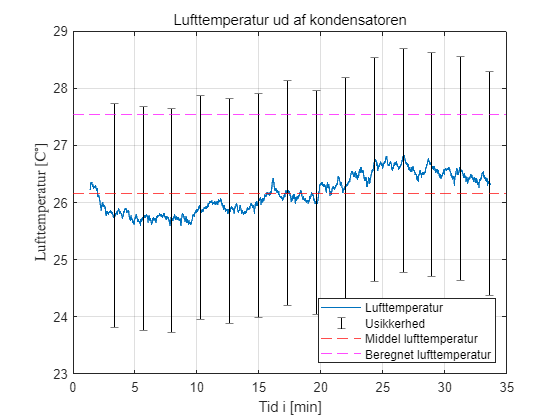

yline(mean(T_luft),"r--")
yline(T_luft_teo,"m--")

hold on
errorbar(xlin(gg),T_luft(gg-100),fejl,"k","linestyle","none")

grid("on")
title("Lufttemperatur ud af kondensatoren","FontWeight","normal")

xlabel("Tid i [min]")
ylabel("Lufttemperatur [C$^\circ$]","Interpreter","latex")

legend("Lufttemperatur","Middel lufttemperatur","Beregnet lufttemperatur","Usikkerhed","location","southeast")

exportgraphics(gcf, "LuftUdSammenligning.png")

% 
% tfilm = (22+82.253)/2
% 
% t_fi = 82.253;    % Kølemiddel temp ind
% t_fu = 30;    % Kølemiddel temp ud
% 
% t_lu = T_luft_teo;    % Luft temp ud
% t_li = 22;    % Luft temp inid
% 
% T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li));
% T_LM = vpa(T_LM, 4);
% 
% 
% cp_luft = vpa(CP.PropsSI("C","T",273.15 + tfilm,"P",101325,"air"),4)
% 
% R_tot = 0.0093;
% 
% 
% phi_ydelse = vpa(separateUnits(T_LM)/R_tot,6)
% phi_luft = vpa(separateUnits(qm_luft)*cp_luft*(t_lu - 22),6)
% phi_fluid = vpa(separateUnits(qmr)*cp_r134_ind*(t_fu - 82.253),6)
% phi_fase = vpa(separateUnits(qmr)*(h_ud - h_ind),6)
% 
% 
% 
% vpa(separateUnits(qmr)*(h_ud-h_ind),6)








